**APPLICATION - 1**

**FREQUENCY ESTIMATION OF A NOISY SIGNAL** 

**ALGORITHM - 1 : FAST FOURIER TRANSFORM**

close all; 
clear all; 
clc;

% Assume we capture 8192 samples at 1kHz sample rate
Nsamps = 8192;
fsamp = 1000;
Tsamp = 1/fsamp;
t = (0:Nsamps-1)*Tsamp;+

% Assume the noisy signal is exactly 123Hz
fsig = 123;
signal = sin(2*pi*fsig*t);
noise = 1*randn(1,Nsamps);
x = signal + noise;

% Plot time-domain signal
subplot(2,1,1);
plot(t, x);
ylabel('Amplitude'); xlabel('Time (secs)');
axis tight;
title('Noisy Input Signal');

% Choose FFT size and calculate spectrum
Nfft = 1024;
[Pxx,f] = pwelch(x,gausswin(Nfft),Nfft/2,Nfft,fsamp);

% Plot frequency spectrum
subplot(2,1,2);
plot(f,Pxx);
ylabel('PSD'); xlabel('Frequency (Hz)');
grid on;

% Get frequency estimate (spectral peak)
[~,loc] = max(Pxx);
FREQ_ESTIMATE = f(loc)

FREQ_ESTIMATE = 123.0469

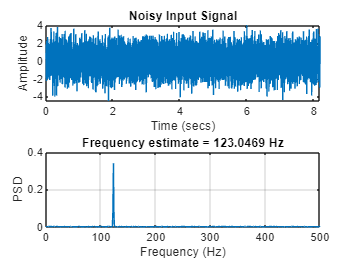

title(['Frequency estimate = ',num2str(FREQ_ESTIMATE),' Hz']);

**ALGORITHM - 2 : SUBSPACE METHOD**

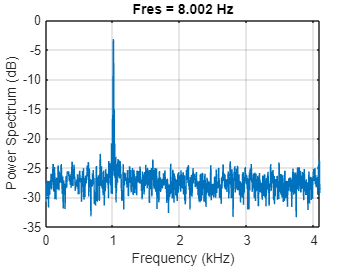

close all; 
clear all; 
clc;

% Assume we capture 8192 samples at 1kHz sample rate
Nsamps = 8192;
fsamp = 1000;
Tsamp = 1/fsamp;
t = (0:Nsamps-1)*Tsamp;

% Assume the noisy signal is exactly 123Hz
fsig = 123;
signal = sin(2*pi*fsig*t);
noise = 1*randn(1,Nsamps);
x = signal + noise;

pspectrum(x,Nsamps,'Leakage',1)

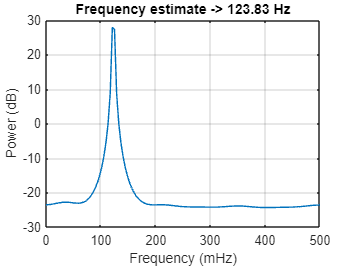

[X,R] = corrmtx(x,14,'mod');

peig(R,2,[],1,'corr')

title(['Frequency estimate -> 123.83 Hz'] )


%findpeaks(pmusic(R,2,[],1,'corr'))


**APPLICATION - 2**

**POWER SYSTEM [FREQUENCY ESTIMATION OF TWO COMPLEX EXPONENTIAL SIGNALS]**

**ALGORITHM - 1 : FAST FOURIER TRANSFORM**

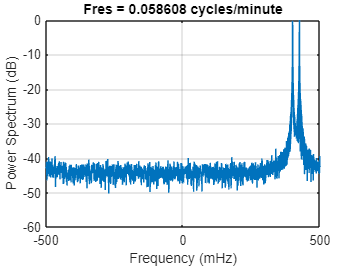

close all; 
clear all; 
clc;

% Assume we capture 8192 samples at 1kHz sample rate
Nsamps = 0:8191;
fsamp = 1000;
Tsamp = 1/fsamp;
t = (0:Nsamps-1)*Tsamp;

% The signal consists of two complex exponentials (sine waves) 
% with frequencies of 0.4 Hz and 0.425 Hz 
% additive complex white Gaussian noise.

x = exp(1j*2*pi*0.4*Nsamps) + exp(1j*2*pi*0.425*Nsamps)+ ...
    0.2/sqrt(2)*(randn(size(Nsamps))+1j*randn(size(Nsamps)));

pspectrum(x,Nsamps,'Leakage',1)

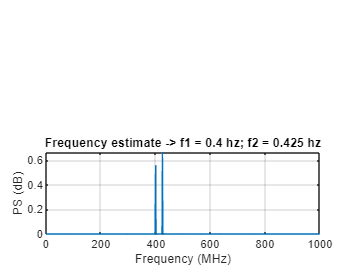

[X,R] = corrmtx(x,14,'mod');


% Choose FFT size and calculate spectrum
Nfft = 1024;
[Pxx,f] = pwelch(x,gausswin(Nfft),Nfft/2,Nfft,fsamp);

% Plot frequency spectrum
subplot(2,1,2);
plot(f,Pxx);
ylabel('PS (dB)'); xlabel('Frequency (MHz)');
grid on;

% Get frequency estimate (spectral peak)
[~,loc] = max(Pxx);
FREQ_ESTIMATE = f(loc);
title(['Frequency estimate -> ','f1 = 0.4 hz; f2 = 0.425 hz']);

**ALGORITHM - 2 : SUBSPACE METHOD**

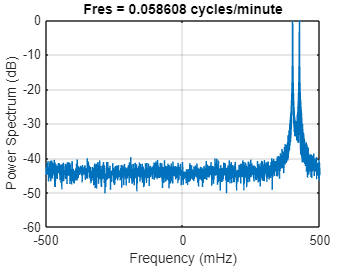

close all; 
clear all; 
clc;

% Created a complex-valued signal 8191 samples in length.
n = 0:8191;

% The signal consists of two complex exponentials (sine waves) 
% with frequencies of 0.4 Hz and 0.425 Hz 
% additive complex white Gaussian noise.

x = exp(1j*2*pi*0.4*n) + exp(1j*2*pi*0.425*n)+ ...
    0.2/sqrt(2)*(randn(size(n))+1j*randn(size(n)));

pspectrum(x,n,'Leakage',1)

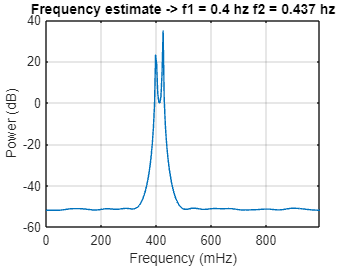

[X,R] = corrmtx(x,14,'mod');

peig(R,2,[],1,'corr')
title([' ']);

title(['Frequency estimate -> ' ...
    'f1 = 0.4 hz' ...
    ' f2 = 0.437 hz'])


%findpeaks(pmusic(R,2,[],1,'corr'))